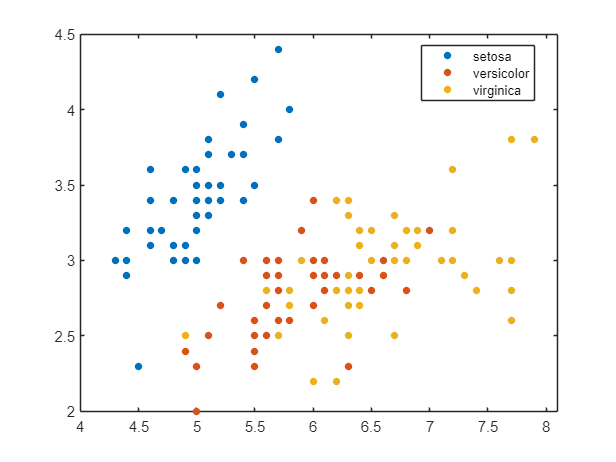

clear
load fisheriris
X = meas;
Y = string(species);

cv = cvpartition(Y,'Holdout',0.5);
X_training = X(cv.training,:); Y_training = Y(cv.training,:);
X_test = X(cv.test,:);

fileDirectory = fullfile('D:/Proton Drive/Lasseb200/My files/Master/MachineLearning');
addpath(fullfile(fileDirectory,'k-NN'));
Y_pred = kNN(X_training,Y_training,X_test,5);

Y_test = Y(cv.test,:);
gscatter(X_training(:,1),X_training(:,2),Y_training)
hold on
gscatter(X_test(:,1),X_test(:,2),Y_pred)
hold off

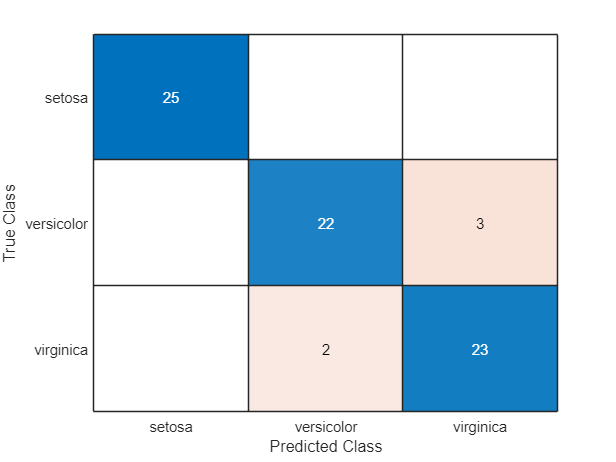


confusionchart(Y_test, Y_pred);